# Actividad 1: Sistema de Primer Orden 

clc
clear

#### Caso I

a=1; b=1;

#### Caso II

% a=10; b=10;

#### Caso III

% a=100; b=100;

Corremos la simulación y tomamos los datos

out = sim('sesion2_act1'); %correr simulación

tf=out.tf;      %salida transfer function.
dif=out.dif;    %salida ec. diferencial

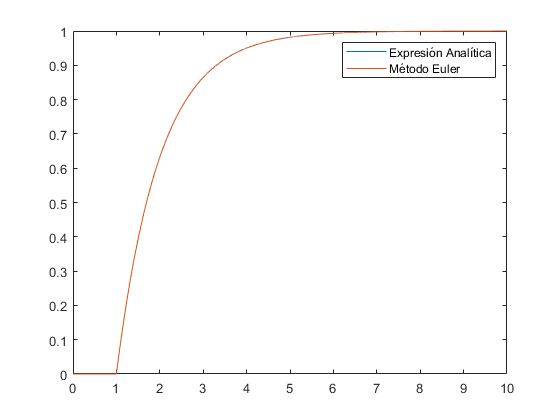

t_len=10; %tiempo de simulación

t = linspace(0, t_len, length(tf));

N=(t_len/0.001)+1;

h=heaviside(t-1);

%plot(t,h)

expr=(b/a)*(h.*(1-exp(-1*a*(t-1))));  %expresión analitica
 plot(t,expr)
 hold on
 plot(t,dif)
 legend('Expresión Analítica','Método Euler')

Error Cuadratico Medio

E=immse(expr, tf.')

# Actividad 2: Sistema de Segundo Orden

## Respuesta Escalón e Impulso

clc
clear
s=tf('s');

Constantes de de casos I, II, III, IV y V

a1 = [2*0.7*1, 2*0.3*1, 2*0.7*10, 2*0.3*10, 2*0.7*1];
a0 = [1, 1, 100, 100,1];
b1 = [0, 0, 0, 0, -1];
b0 = [1, 1, 1, 1, 1];

Identificadores de funciones

G_c = @(x) (b1(x)*s+b0(x))/(s^2+a1(x)*s+a0(x));

Polos y ceros

for i = (1 : length(a1) )  
    n_caso_string="Caso "+string(i);

    disp(n_caso_string)
     
    P=pole(G_c(i));
    Z=zero(G_c(i));
    disp("Polos en: ");
    disp(P);

    if Z ~= 0
        disp("Ceros en: ");
        disp(Z);
    else 
        disp("Sin ceros"); 
    end
    
    disp("----------------------")  
end

Caso 1


Polos en: 


  -0.7000 + 0.7141i
  -0.7000 - 0.7141i



Sin ceros


----------------------


Caso 2


Polos en: 


  -0.3000 + 0.9539i
  -0.3000 - 0.9539i



Sin ceros


----------------------


Caso 3


Polos en: 


  -7.0000 + 7.1414i
  -7.0000 - 7.1414i



Sin ceros


----------------------


Caso 4


Polos en: 


  -3.0000 + 9.5394i
  -3.0000 - 9.5394i



Sin ceros


----------------------


Caso 5


Polos en: 


  -0.7000 + 0.7141i
  -0.7000 - 0.7141i



Ceros en: 


     1



----------------------


Graficando la respuesta impulso de los 4 primeros casos

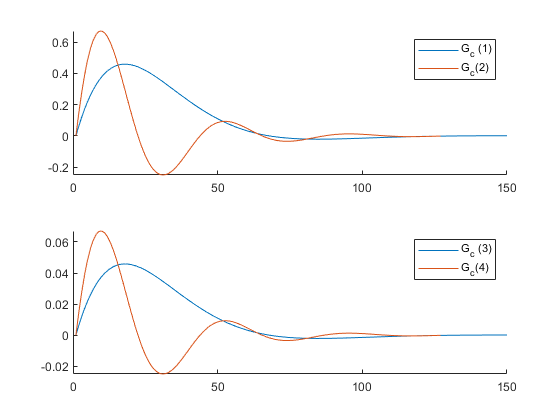

subplot(2,1,1)
hold on
plot( impulse(G_c(1)))
plot( impulse(G_c(2)))
legend('G_c (1)', 'G_c(2)')

subplot(2,1,2)
hold on
plot( impulse(G_c(3)) )
plot( impulse(G_c(4)) )
legend('G_c (3)', 'G_c(4)')

Respuesta Escalon

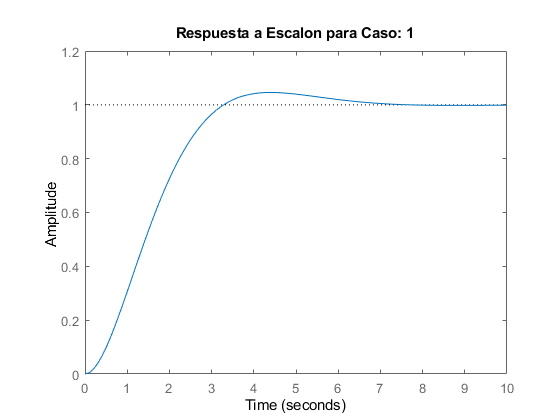

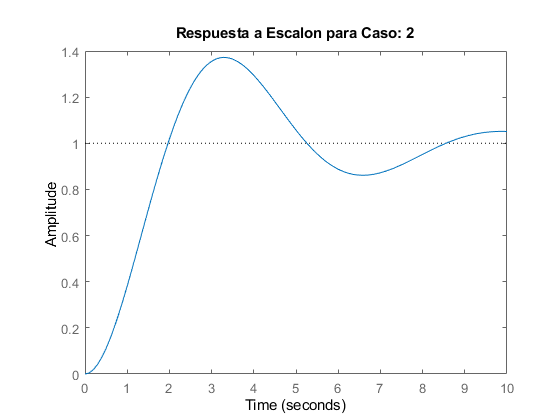

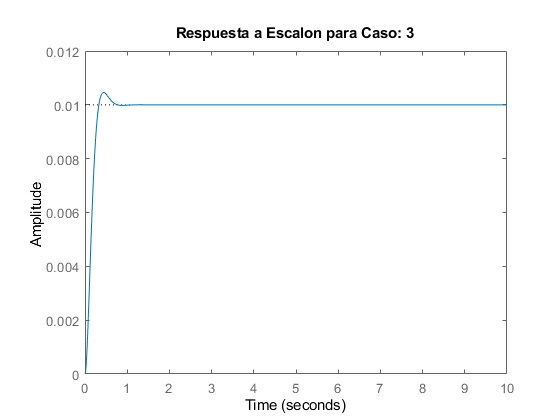

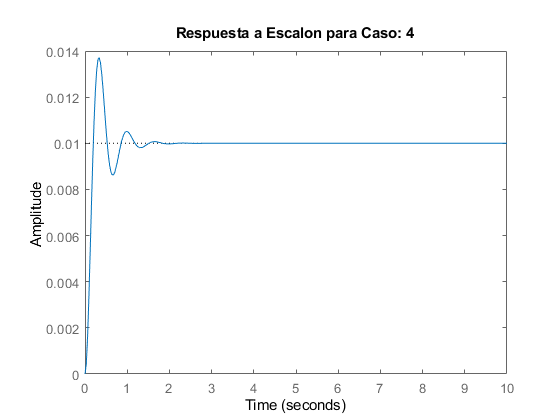

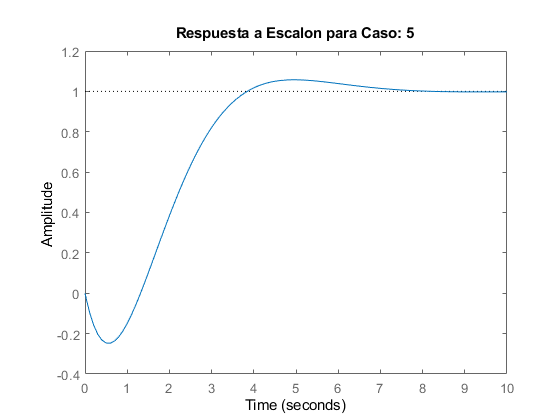


for i = (1 : length(a1) )
    %2.3
    titulo='Respuesta a Escalon para Caso: ' + string(i);
    figure
    step(G_c(i),10)
    title(titulo)
end

for i = [1 : length(a1) ]
   %2.4
    [A,B]=step(G_c(i),10);
    
    P=pole(G_c(i));
    Z=zero(G_c(i));
    Undershoot =min(A); %undershoot
    Tvalle =B(find(A==min(A))); %tiempo de valle
    Overshoot =max(A); %overshoot
    Tmax =B(find(A==max(A))); % tiempo de peak
    Final =A(length(A)); %salida estacionaria.
    
   datosenal= 'Caso: ' + string(i) + '\n'...
    +'Undershoot: ' + string(Undershoot) + '\n'...
    + 'Tiempo de Valle: ' + string(Tvalle) + '\n'...
    + 'Overshoot: ' + string(Overshoot) +'\n'...
    + 'Tiempo de peak: ' + string(Tmax) + '\n'...
    +'Salida estacionaria:' + string(Final) + '\n';

    sprintf(datosenal)
    
end

ans =     "Caso: 1
     Undershoot: 0
     Tiempo de Valle: 0
     Overshoot: 1.046
     Tiempo de peak: 4.4
     Salida estacionaria:0.99873
     "


ans =     "Caso: 2
     Undershoot: 0
     Tiempo de Valle: 0
     Overshoot: 1.3723
     Tiempo de peak: 3.3
     Salida estacionaria:1.0513
     "


ans =     "Caso: 3
     Undershoot: 0
     Tiempo de Valle: 0
     Overshoot: 0.010459
     Tiempo de peak: 0.43421
     Salida estacionaria:0.01
     "


ans =     "Caso: 4
     Undershoot: 0
     Tiempo de Valle: 0
     Overshoot: 0.013711
     Tiempo de peak: 0.33742
     Salida estacionaria:0.01
     "


ans =     "Caso: 5
     Undershoot: -0.24751
     Tiempo de Valle: 0.6
     Overshoot: 1.0574
     Tiempo de peak: 5
     Salida estacionaria:0.99776
     "


%obtener tiempo valle último caso.




## Respuesta en Frecuencia

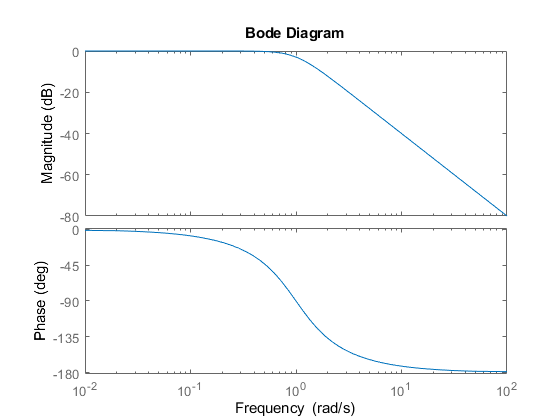


t1=linspace(0,30,30001);
bode(G_c(1));


%------------------entrada 1
[A1,B1]=freqresp(G_c(1),3)

A1 = -0.0980 - 0.0514i

B1 = 3

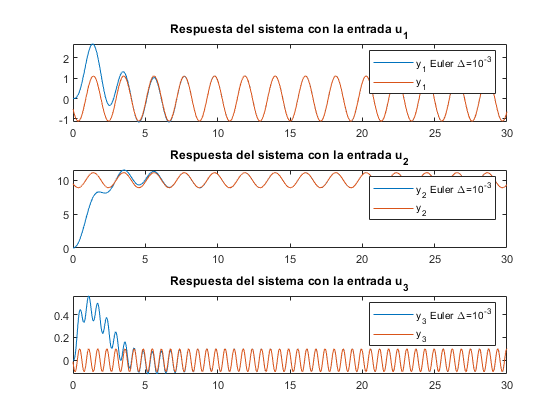

u1abs=abs(A1); u1fase=angle(A1); %
y_m_1=10*u1abs*sin(3*t1+u1fase); %stationary output of the system
%------------------entrada 2
[A2,B2]=freqresp(G_c(1),0);
u2abs=abs(A2); u2fase=angle(A2);
y_m_2=10*( u2abs*cos(u2fase)  +  u1abs*sin(3*t1+u1fase));
%------------------entrada 3
[A3,B3]=freqresp(G_c(1),10);
u3abs=abs(A3); u3fase=angle(A3);
y_m_3=10*u3abs*sin(10*t1+u3fase);

sys = G_c(1);
out = sim('sesion2_act2'); %run the simulation

y1 = out.y1;
y2 = out.y2;
y3 = out.y3;

figure(2)
subplot(3,1,1)
plot(t1,y1)
hold on
plot(t1,y_m_1)
legend("y_1 Euler \Delta=10^{-3}", "y_1 ")
title('Respuesta del sistema con la entrada u_1')

subplot(3,1,2)

plot(t1,y2)
hold on
plot(t1,y_m_2)
legend("y_2 Euler \Delta=10^{-3}" , "y_2")
title('Respuesta del sistema con la entrada u_2')


subplot(3,1,3)

plot(t1,y3)
hold on
plot(t1,y_m_3)
legend("y_3 Euler \Delta=10^{-3}", "y_3 ")
title('Respuesta del sistema con la entrada u_3')